# Computer Vision Introduction

Computer vision is automation of tasks that mimic human response to visual information. Computers gain high-level understanding and take actions from digital images or videos.

## **Image Manipulation**

**Read Images from a File**

The photo of students walking is a 600x400 pixel image. First, download the image with this code or by manually saving the image to the run folder.

url = 'http://apmonitor.com/pds/uploads/Main/students_walking.jpg';
filename = 'students_walking.jpg';
outfilename = websave(filename,url);
image = imread(outfilename);

The returned object *im* is a *400x600x3* array of integers that represent RGB (Red, Green, Blue) values but in Blue, Green, Red order.

**Resize Image**

The size of an image is available with the *shape* property to return the height (*h*), width (*w*), and color (*c*).

[h, w, c] = size(image);

An image can be resized by either specifying the new image dimension. The original photo of the students is 600x400 and the image is reduced to 300x200:

image1 = imresize(image,[300,200]);

The image can also be resized by specifying a scaling factor (0.5) for the x and y dimensions. Use *None* for the image dimension to use the scaling factors.

image2 = imresize(image,0.5);

With a target image size for one dimension, calculate the other dimension. In this case, the width is specified as 300px and the new image height is calculated from the width scaling factor.

width = 300; % new width
scale = width/w; % scaling factor
height = h * scale; % new height
dim = [width,height];
image3 = imresize(image,dim);

**View Images on a Display**

The simplest method of viewing an image is to use the imshow function.

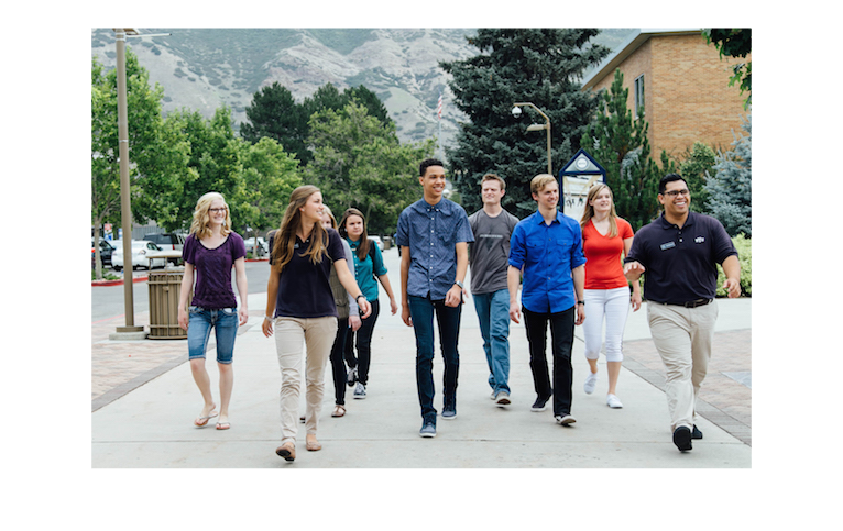

imshow(image)

Alternatively, you can create a cell of the image data variables then use montage to view the images in the same figure. 

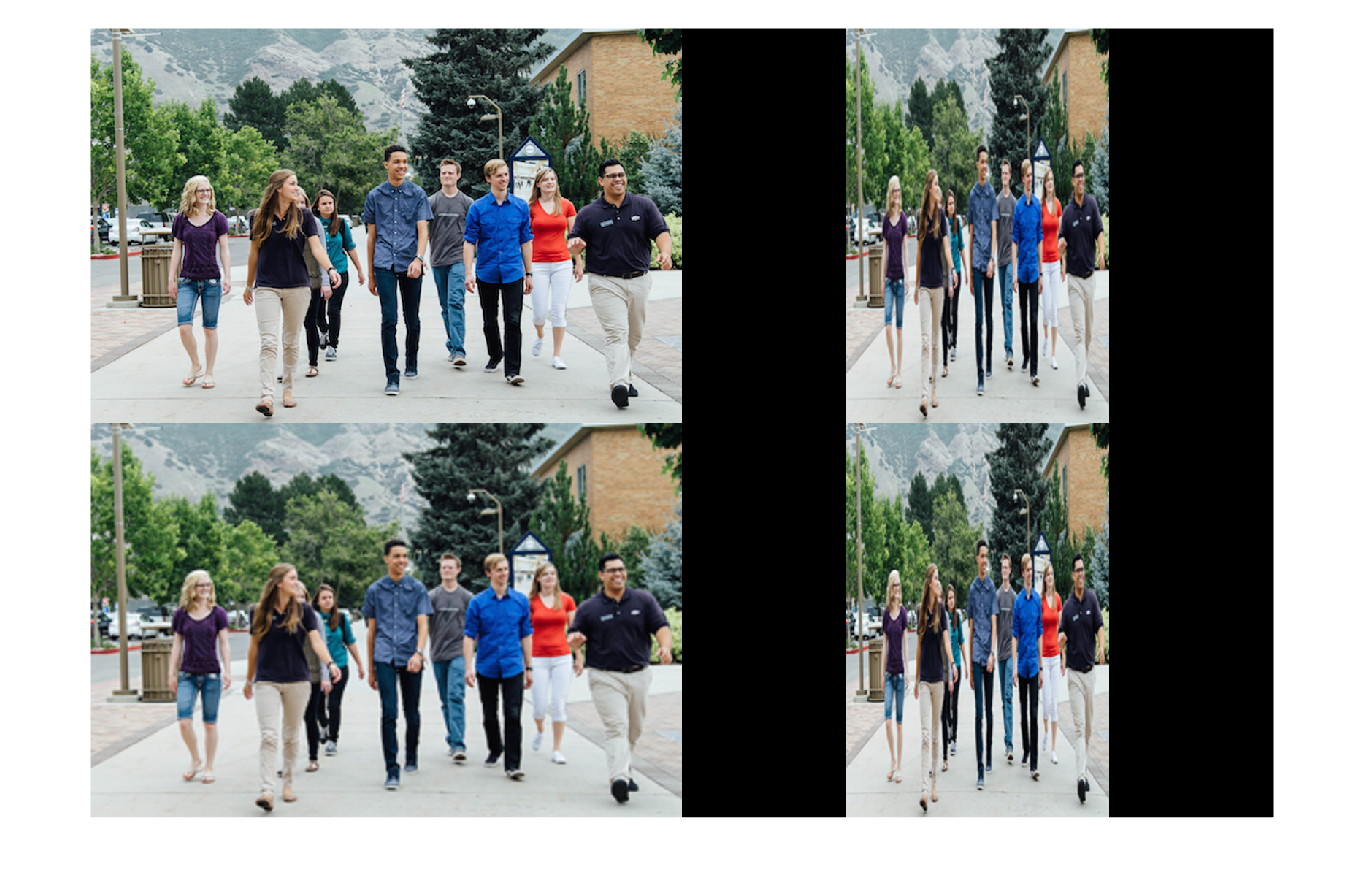

imageArray = {image image1 image2 image3};
montage(imageArray)

**Write Images to a File**

The [*imwrite*](https://www.mathworks.com/help/matlab/ref/imwrite.html) function saves the image to a file with the format specified by the filename extension (BMP, JPG, JPEG, PNG, WEBP, TIFF, and others). With 'imwrite(image,'students.png')'', the image is saved in PNG format.

imwrite(image,"students.png")

## Video Manipluation

**Capture and Write Video**

Video capture from a camera is with the webcam function. A new window *Video Player* is opened to show each frame. The object *out* is a writeVideo to save each frame to an *avi* file for 5 seconds.

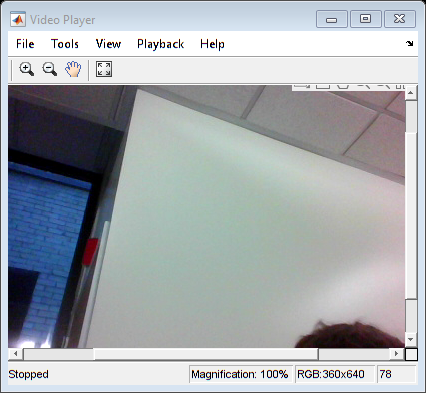

% Initialize the camera
cam = webcam(1);
% Set up the video file writer
writer = VideoWriter('video.avi');
writer.FrameRate = 30;
open(writer);

% Set up the video player
player = vision.VideoPlayer;

% Capture the video for 5 seconds and write it to the file
tic
while toc < 5
    % Capture a frame
    frame = snapshot(cam);
    
    % Display the frame
    step(player, frame);
    
    % Write the frame to the file
    writeVideo(writer, frame);
end

% Clean up
closePreview( cam )
clear cam;
release(player);

close(writer);

**Application**

Modify the video capture script to view the difference between successive frames. Any moving objects or changes in the scene will be highlighted in the displayed difference image. The intensity of the highlights depends on the magnitude of the pixel differences. More significant changes will appear brighter in the image. Displaying the difference image is often used for applications such as motion detection or tracking moving objects and changes in a video feed. 

To summarize the text above, the more you move, the more changes you will see on the screen showing you the difference between the two images taken while recording. The white lines that appear are the differences between the two images showing you how the object moved and what the computer picked up. If you do not move or are in a dark room, you will only see a black screen. Please ensure that you are in a well lit room and ensure that you move the object infront of the camera to view all affects that the following code provides.

The following code will record and show the video below the scripted code. This code will record a video for 15 seconds.

After you have stopped the video capturing, the last image recorded by the program will appear at the end of the script. This image as no significance to the script. It is simply the last image that the code records as described above.

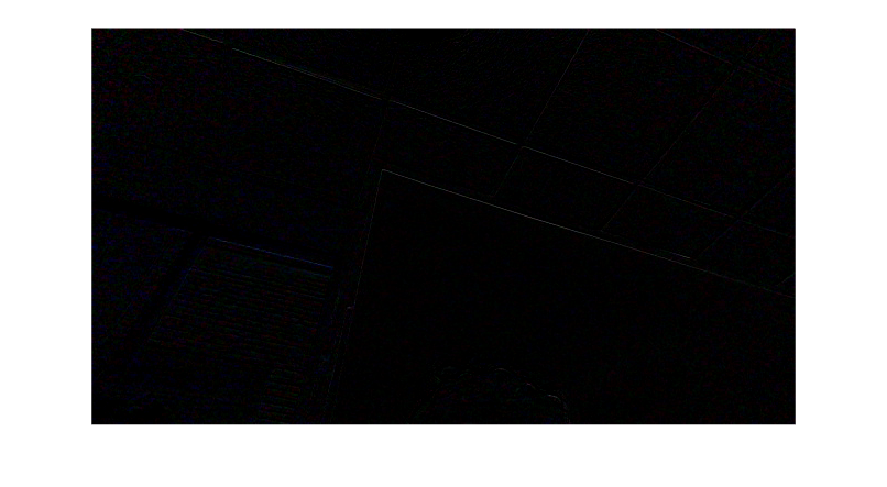

tic % start timer

% Initialize the camera
cam = webcam(1);

% Set up the video player
player = vision.VideoPlayer;

% Set up previous frame variable
prev_frame = [];

% % Create break for while loop
DlgH = figure;

while toc < 15    % run for 15 seconds
    % Capture a frame
    frame = snapshot(cam);

    if ~isempty(prev_frame)
        % Take the difference between frames
        diff_frame = abs(frame - prev_frame);
        % Display the frame
        imshow(diff_frame);     
    end
    
    % update the previous frame
    prev_frame = frame;
end

% Clean up
closePreview( cam )
clear cam;
release(player);

This code is the same as before but will continue recording until you click the break button. Click break in the bottom left to stop the video capturing.

runVideo = false;

if runVideo
    % Initialize the camera
    cam = webcam(1);
    
    % Set up the video player
    player = vision.VideoPlayer;
    
    % Set up previous frame variable
    prev_frame = [];
    
    % Create break for while loop
    DlgH = figure;
    H = uicontrol('Style', 'PushButton', ...
                        'String', 'Break', ...
                        'Callback', 'delete(gcbf)');
    
    % Capture video and display
    while (ishandle(H))
        % Capture a frame
        frame = snapshot(cam);
    
        if ~isempty(prev_frame)
            % Take the difference between frames
            diff_frame = abs(frame - prev_frame);
            % Display the frame
            imshow(diff_frame);     
        end
        
        % update the previous frame
        prev_frame = frame;
    
    end

    % Clean up
    closePreview( cam )
    clear cam;
    release(player);
end

## **Further Training**

Learn about the role of features in computer vision, how to label data, train an object detector, and track wildlife in video with the [**Computer Vision Onramp**](https://matlabacademy.mathworks.com/details/computer-vision-onramp/orcv) course. 

[USB Camera Package](https://www.mathworks.com/help/supportpkg/usbwebcams/index.html)